## Ecuatii neliniare

log(2) / log((1 + sqrt(5)) / 2)

ans =    1.440420090412556


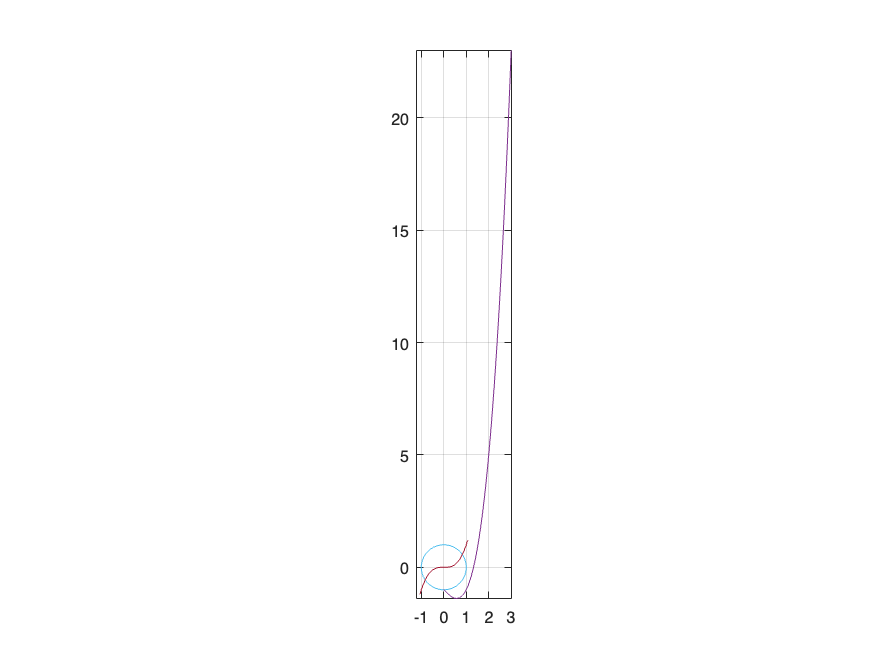

f = @(x) x.^3 - x - 1;
fplot(f, [0, 3])
grid on

fd = @(x) 3 * x .^ 2 - 1;
x0 = 2;
[z1, ni] = Newton(f, fd, x0, 1e-8, 0)

z1 =    1.324717957244746


ni =      6


f(z1)

ans =      2.220446049250313e-16


x0 = 1; x1 = 2;
[z2, n2] = Secant(f, x0, x1, 1e-8, 0)

z2 =    1.324717957244670


n2 =      7


f(z2)

ans =     -3.228528555609955e-13


phi = @(x) (x+1) .^(1/3);
x0 = 1;
[z3, n3] = Mas(phi, x0, 1e-8, 0)

z3 =    1.324717956483471


n3 =     12


f(z3)

ans =     -3.246559465708287e-09


T = 90; e = 0.8; t = 9; 
kepler = @(E)  E - e * sin(E) - 2*pi*t/T;
keplerD = @(E) 1 - e * cos(E);
E0 = 1;
[r1, n1] = Newton(kepler, keplerD, E0, 1e-9)

r1 =    1.419135783830583


n1 =      5
